## **Stewart Platform Simulation**

The purpose of this script is to show the calculations needed for a stewart platform and help select parameters for the platform.

### **Constant Values **

P = 115.47; % Platform size constant (mm)
B = 115.47; % Base size constant (mm)

a = 100; % Controlled arm length (mm)
b = 150; % Uncotrolled arm (mm)

h_0 = 100 ; % Default platform height (mm)

### **Inputed command**

% pitch is rotation about the y-axis (right hand rule thumb pointing towards
% neg y :(  )
pitch =-20

pitch = -20

% roll is rotation about the x-axis (right hand rule thumb pointing towards
% pos x)
roll = 20

roll = 20

z =    10

z = 10

### **Platform and Base Vectors **

% Platform vectors from center of platform to corner in frame of platform
p1 = (P * [cosd(0) sind(0) 0])';
p2 = (P * [cosd(120) sind(120) 0])';
p3 = (P * [cosd(240) sind(240) 0])';

% Base vectors from center of base to edge in regular frame of base
B1 = (B * [cosd(0) sind(0) 0])';
B2 = (B * [cosd(120) sind(120) 0])';
B3 = (B * [cosd(240) sind(240) 0])';

### **Rotation Matrix Calculation**

R = calculateRotationMatrix(pitch, roll)

R =     0.9397   -0.1170   -0.3214
         0    0.9397   -0.3420
    0.3420    0.3214    0.8830


T = ([0 0 h_0] + [0 0 z])';

% platform vectors in regular frame of base
P1 = (T + R * p1)'

P1 =   108.5063         0  149.4931


P2 = (T + R * p2)'

P2 =   -65.9509   93.9692  122.3928


P3 = (T + R * p3)'

P3 =   -42.5554  -93.9692   58.1141



% Used for plotting platform and base
X = [P1(1), P2(1), P3(1), B1(1), B2(1), B3(1)];
Y = [P1(2), P2(2), P3(2), B1(2), B2(2), B3(2)];
Z = [P1(3), P2(3), P3(3), B1(3), B2(3), B3(3)];

### **Calculating l vectors**

l1 = (T + R*p1 - B1)'

l1 =    -6.9637         0  149.4931


l2 = (T + R*p2 - B2)'

l2 =    -8.2159   -6.0307  122.3928


l3 = (T + R*p3 - B3)'

l3 =    15.1796    6.0307   58.1141



magl1sqrd = l1(1)^2 + l1(2)^2 + l1(3)^2

magl1sqrd = 2.2397e+04

magl2sqrd = l2(1)^2 + l2(2)^2 + l2(3)^2

magl2sqrd = 1.5084e+04

magl3sqrd = l3(1)^2 + l3(2)^2 + l3(3)^2

magl3sqrd = 3.6440e+03


magl1 = sqrt(magl1sqrd)

magl1 = 149.6552

magl2 = sqrt(magl2sqrd)

magl2 = 122.8164

magl3 = sqrt(magl3sqrd)

magl3 = 60.3659



% phi gives us an idea of the error of this calculation, in actual
% situation phi is set at 0, -60, and 60
phi1 = atand(l1(2)/l1(1))

phi1 = 0

phi2 = atand(l2(2)/l2(1))

phi2 = 36.2798

phi3 = atand(l3(2)/l3(1))

phi3 = 21.6675

### **Calculating motor angle**

% beta represents the angle between controlled arm and l vector
beta1 = acosd((-b^2+a^2+magl1sqrd) / (2*a*magl1))

beta1 = 70.6918

beta2 = acosd((-b^2+a^2+magl2sqrd) / (2*a*magl2))

beta2 = 83.9617

beta3 = acosd((-b^2+a^2+magl3sqrd) / (2*a*magl3))

beta3 = 137.1826


% alpha represents the angle between the z-axis and the l vector
% pos means l in same direction as B vector, neg means l away from B vector
alpha1 = 90 - acosd( dot(B1,l1) / (B*magl1) )

alpha1 = -2.6670

alpha2 = 90 - acosd( dot(B2,l2) / (B*magl2) )

alpha2 = -0.5201

alpha3 = 90 - acosd( dot(B3,l3) / (B*magl3) )

alpha3 = -12.2542


% Old way of doing it that couldn't be negative
%alpha1 = atand( sqrt(l1(1)^2+l1(2)^2) / l1(3) )
%alpha2 = atand( sqrt(l2(1)^2+l2(2)^2) / l2(3) )
%alpha3 = atand( sqrt(l3(1)^2+l3(2)^2) / l3(3) )

% psi represents the motor angle, angle between controlled arm and z-axis
psi1 = alpha1 + beta1

psi1 = 68.0248

psi2 = alpha2 + beta2

psi2 = 83.4417

psi3 = alpha3 + beta3

psi3 = 124.9285

### **Calculating other things for plot**

% gamma represents the angle between controlled arm and uncontrolled arm
gamma1 = acosd((-magl1sqrd+a^2+b^2) / (2*a*b))

gamma1 = 70.3193

gamma2 = acosd((-magl2sqrd+a^2+b^2) / (2*a*b))

gamma2 = 54.5116

gamma3 = acosd((-magl3sqrd+a^2+b^2) / (2*a*b))

gamma3 = 15.8740


% rho represents the angle between z-axis and uncontrolled arm
% pos rho means uncontrolled arm towards middle, negative means
% uncontrolled arm away from center
rho1 = 180 - psi1 - gamma1

rho1 = 41.6559

rho2 = 180 - psi2 - gamma2

rho2 = 42.0467

rho3 = 180 - psi3 - gamma3

rho3 = 39.1975


% Uncontrolled arm vectors
a1 = (a * [cosd(0)*sind(psi1) sind(0)*sind(psi1) cosd(psi1)])';
a2 = (a * [cosd(120)*sind(psi2) sind(120)*sind(psi2) cosd(psi2)])';
a3 = (a * [cosd(240)*sind(psi3) sind(240)*sind(psi3) cosd(psi3)])';

% Controlled arm vectors
b1 = (b * [cosd(0)*sind(-rho1) sind(0)*sind(-rho1) cosd(-rho1)])';
b2 = (b * [cosd(120)*sind(-rho2) sind(120)*sind(-rho2) cosd(-rho2)])';
b3 = (b * [cosd(240)*sind(-rho3) sind(240)*sind(-rho3) cosd(-rho3)])';

### **3D Plot**

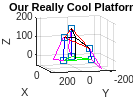

% Create scatter3 of X, Y, and Z
s = scatter3(X,Y,Z,"Marker","square","DisplayName","Z");

% Add xlabel, ylabel, zlabel, title, and legend
axis([-B B -B B 0 10])
xlabel("X")
ylabel("Y")
zlabel("Z")
title("Our Really Cool Platform!")
% Draw Platform
line([X(1),X(2), X(3), X(1)], [Y(1), Y(2), Y(3), Y(1)], [Z(1), Z(2), Z(3), Z(1)], 'Color', 'r')
% Draw Base
line([X(4),X(5), X(6), X(4)], [Y(4), Y(5), Y(6), Y(4)], [Z(4), Z(5), Z(6), Z(4)], 'Color', 'g')
% Draw l vectors
line([X(1), X(4)], [Y(1), Y(4)], [Z(1), Z(4)], 'Color', 'blue')
line([X(2), X(5)], [Y(2), Y(5)], [Z(2), Z(5)], 'Color', 'blue')
line([X(3), X(6)], [Y(3), Y(6)], [Z(3), Z(6)], 'Color', 'blue')
% Some black refrence lines
line([0, T(1)], [0, T(2)], [0, T(3)], "Color", "black")
line([X(1),T(1), X(2), T(1),  X(3), T(1), X(1)], [Y(1),T(2), Y(2), T(2), Y(3), T(2), Y(1)], [Z(1), T(3), Z(2), T(3), Z(3), T(3), Z(1)], 'Color', 'black')

% Draw uncontrolled and controlled arms
line([X(4), X(4)+a1(1), X(4)+a1(1)+b1(1)], [Y(4), Y(4)+a1(2), Y(4)+a1(2)+b1(2)], [Z(4), Z(4)+a1(3), Z(4)+a1(3)+b1(3)], "Color", "magenta")
line([X(5), X(5)+a2(1), X(5)+a2(1)+b2(1)], [Y(5), Y(5)+a2(2), Y(5)+a2(2)+b2(2)], [Z(5), Z(5)+a2(3), Z(5)+a2(3)+b2(3)], "Color", "magenta")
line([X(6), X(6)+a3(1), X(6)+a3(1)+b3(1)], [Y(6), Y(6)+a3(2), Y(6)+a3(2)+b3(2)], [Z(6), Z(6)+a3(3), Z(6)+a3(3)+b3(3)], "Color", "magenta")


xlim([-2*B 2*B])
ylim([-2*B 2*B])
zlim([-50 200])

view([-104 10])


% view([-90, 90])